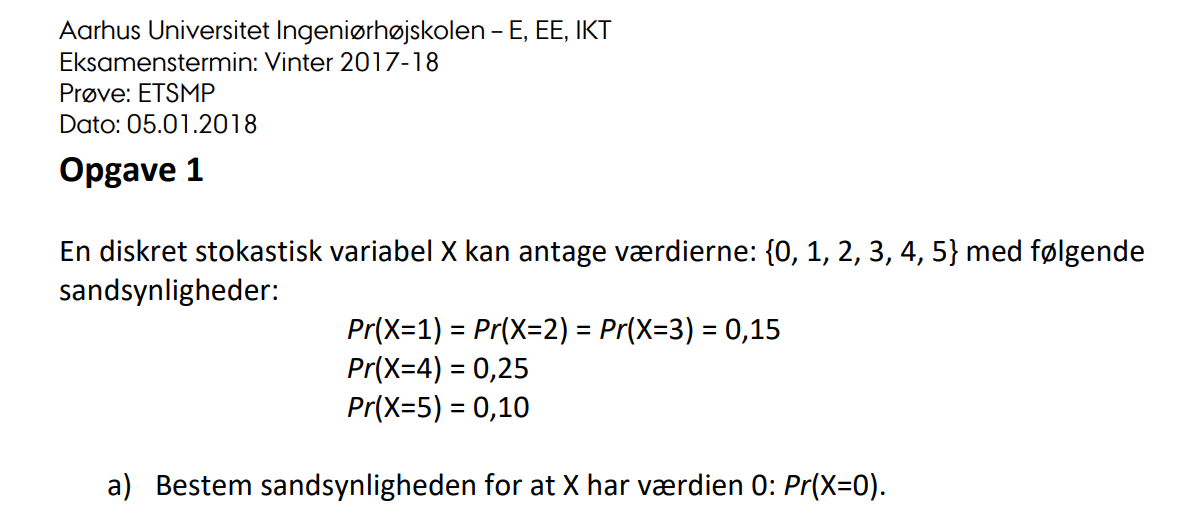

clear
x = [0 1 2 3 4 5]

x =      0     1     2     3     4     5


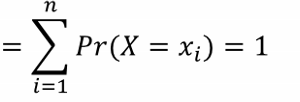

Samlet sandsynlighed er = 1 

Pr_0 = 1 - (0.15+0.15+0.15+0.25+0.10)

Pr_0 = 0.2000

Pr = [0.20 0.15 0.15 0.15 0.25 0.10];

figure()
stem(x, Pr)
title('PMF')
xlabel('x')
ylabel('f_x(x)')

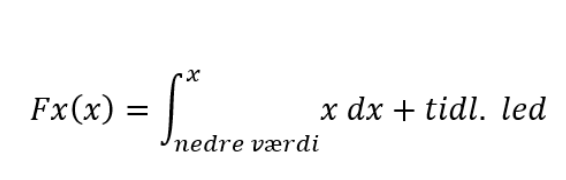

close all
syms x 
Fx(x) = piecewise(...
 x < 0, 0, ...
 x < 1, 0.2,...
 x <= 2, 0.2 + 0.15,...
 x <= 3, 0.2 + 0.15 + 0.15,...
 x <= 4, 0.2 + 0.15 + 0.15 + 0.15,...
 x < 5, 0.2 + 0.15 + 0.15 + 0.15 + 0.25,...
 x >= 5, 0.2 + 0.15 + 0.15 + 0.15 + 0.25 + 0.1)

$$Fx(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<0\\ \frac{1}{5} & \text{ if }x<1\\ \frac{7}{20} & \text{ if }x\leq 2\\ \frac{1}{2} & \text{ if }x\leq 3\\ \frac{13}{20} & \text{ if }x\leq 4\\ \frac{9}{10} & \text{ if }x<5\\ 1 & \text{ if }5\leq x \end{array}\right.$$

fplot(Fx(x),[-2,8],'-r','LineWidth',2)
title('CDF')
xlabel('x')
ylabel('F_X(x)')

c) Bestem middelværdien E[X] af den stokastiske variabel X.


$$\mathit{\mathbf{E}}{\left|\mathit{\mathbf{x}}\right|}=\sum_x x*fx{\left(x\right)}$$


x = 0:1:5

x =      0     1     2     3     4     5


fx = [0.2 0.15 0.15 0.15 0.25 0.1]

fx =     0.2000    0.1500    0.1500    0.1500    0.2500    0.1000


format short
Ex = sum(fx.*x)

Ex = 2.4000

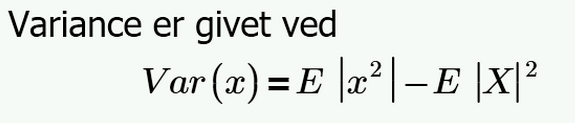

Ex2= sum(x.^2.*fx)

Ex2 = 8.6000

var = Ex2 - Ex^2

var = 2.8400

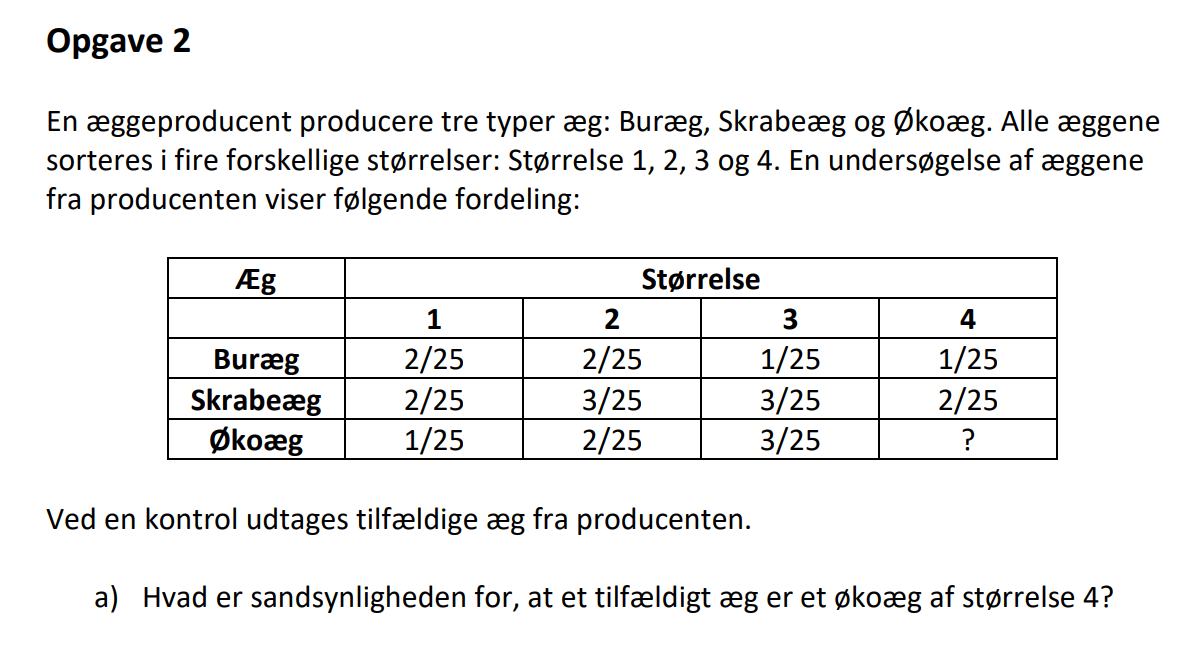

Samlet sandsynlighed er = 1 

bur_1 = 2/25; bur_2 = 2/25; bur_3 = 1/25; bur_4 = 1/25;
skrabe_1 = 2/25; skrabe_2 = 3/25; skrabe_3 = 3/25; skrabe_4 = 2/25;
oko_1 = 1/25; oko_2 = 2/25; oko_3 = 3/25; 
format rat
oko_4 = 1- (sum(bur_1+bur_2+bur_3+bur_4+skrabe_1+skrabe_2+skrabe_3+skrabe_4+oko_1+oko_2+oko_3))

oko_4 =        3/25    


pr_3 = bur_3+skrabe_3+oko_3

pr_3 =        7/25    


pr_bur  = bur_1 + bur_2 + bur_3 + bur_4

pr_bur =        6/25    


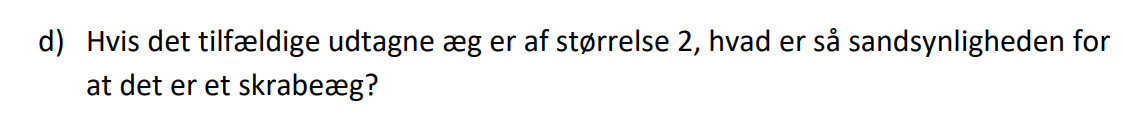

pr_2_skrabe = skrabe_2/sum(bur_2+oko_2+skrabe_2)

pr_2_skrabe =        3/7     


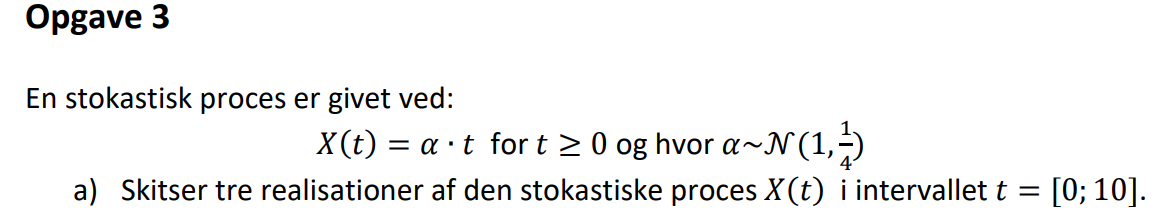

clear all
close all

N = 3; % Antal realisationer
t = [0:10];
mu = 1; variance = 1/4; sigma = sqrt(variance);
a = normrnd(mu, sigma, [1 N])

a =      922/3085       333/1153      3899/3134  


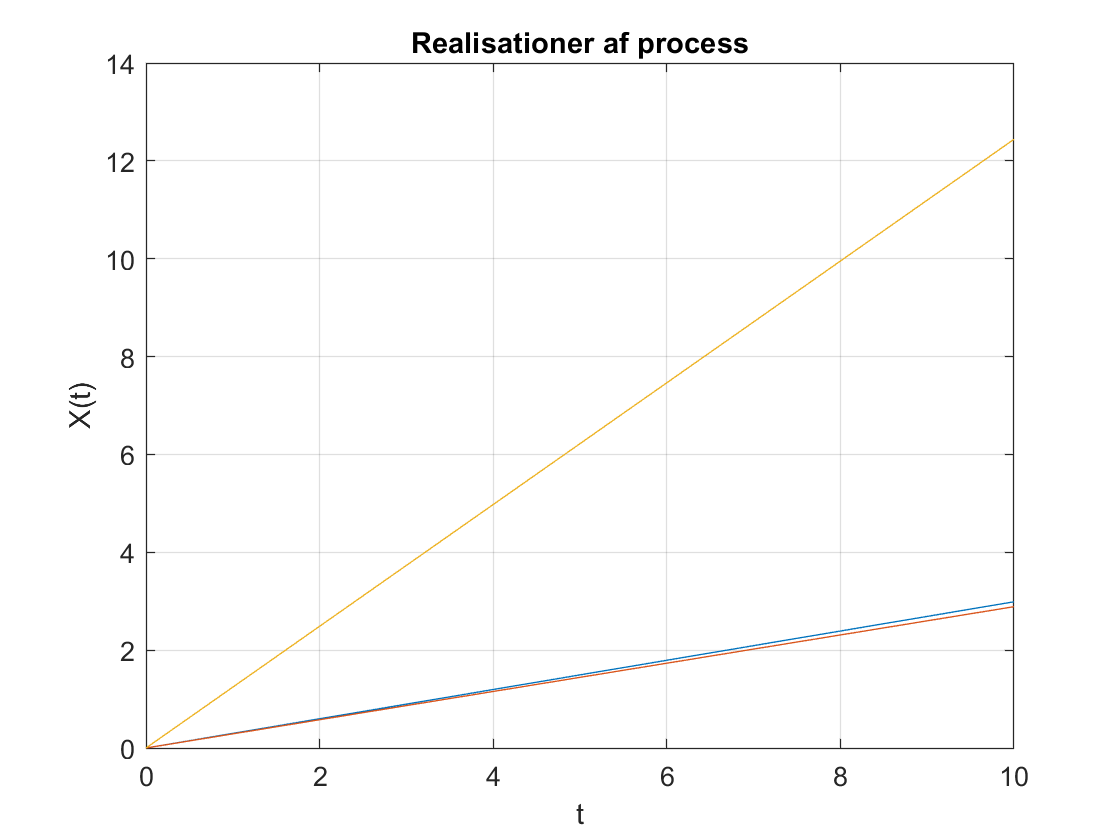

figure()
for i=1:N
    X = a(i).*t;
    plot(t, ones(1,length(t)).*X);
    hold on
end
grid on
xlabel("t"); ylabel("X(t)"); title("Realisationer af process");

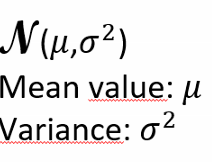

syms t
middel = 1*t

$$middel = t$$

varianse = 1/4*t^2

$$varianse = \frac{t^{2}}{4}$$

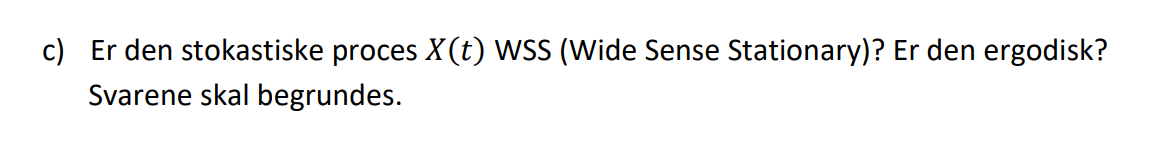

Da processen er afhængig af tiden, og at middelværdien og variansen ændrer sig over tid, så kan vi konstanter at processen er ikke stationær.

Da den ikke er WSS, så kan processen ikke være egodisk.

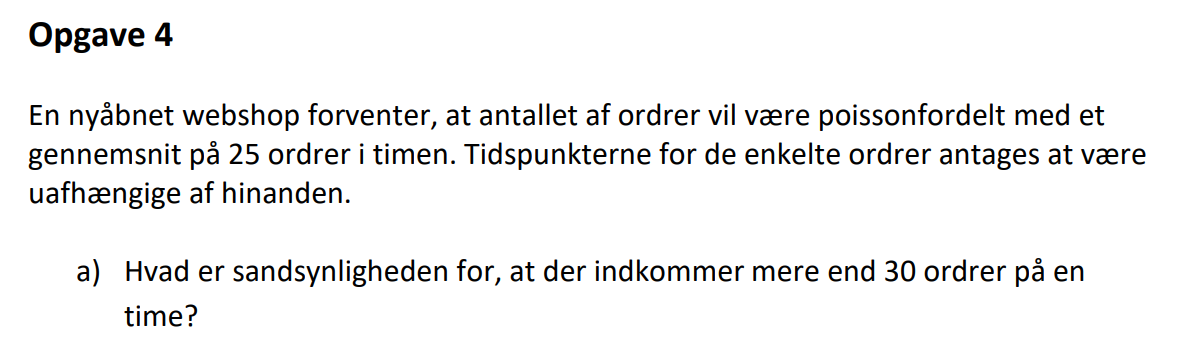

xobs = 25; t = 1;
lambda = xobs/t

lambda =       25       


z = 30; % teststørrelse
format
pval = 1-poisscdf(z,lambda)

pval = 0.1367

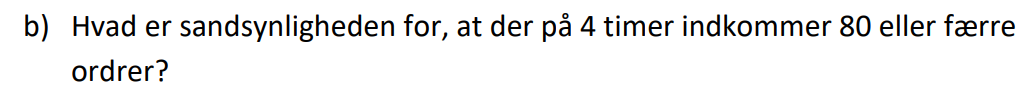

xobs = 25; t = 1;
lambda = xobs/t

lambda = 25

z = 80; % teststørrelse
format
pval = poisscdf(z,lambda*4)

pval = 0.0226

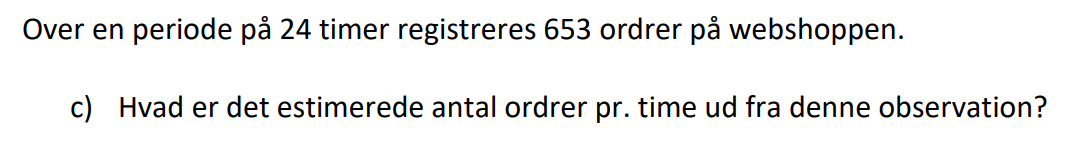

estimate = 653/24

estimate = 27.2083

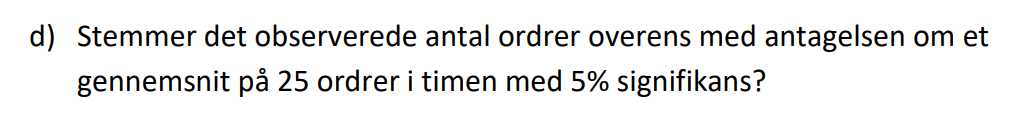

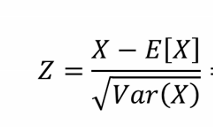

z = (653-(24*25))/sqrt(24*25)

z = 2.1637

pval = 2*(1-normcdf(z))

pval = 0.0305

Da pval er mindre end 5 procent, så fejler vi med at afvise hypotese 0. 

lambda_lower = 1/24 * (653 + 1.96^2/2 - 1.96 * sqrt(653 + 1.96^2/4))

lambda_lower = 25.1999

lambda_upper = 1/24 * (653 + 1.96^2/2 + 1.96 * sqrt(653 + 1.96^2/4))

lambda_upper = 29.3768